genealogicalTreePlot_LineTest

shuai Yang 2020.05.11

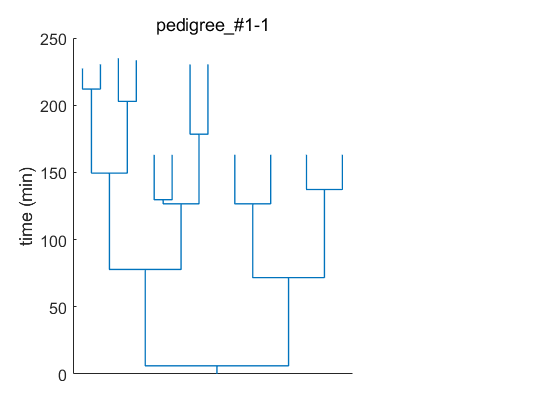

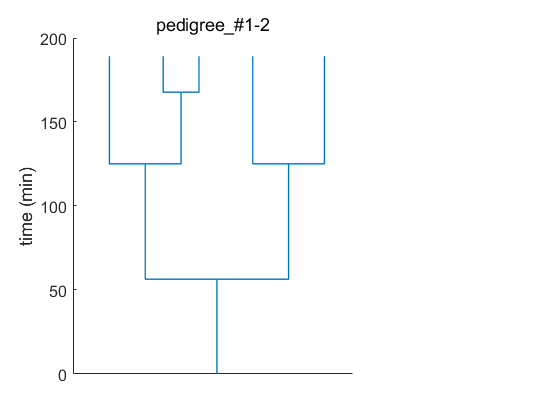

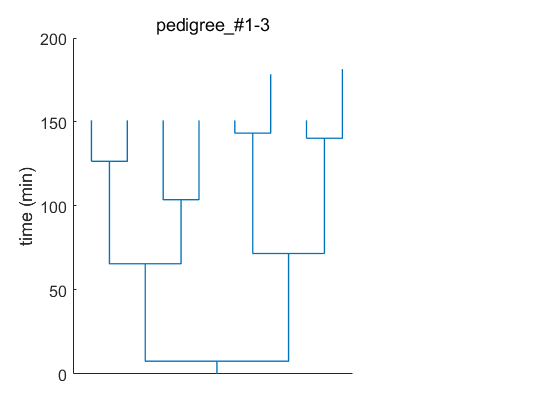

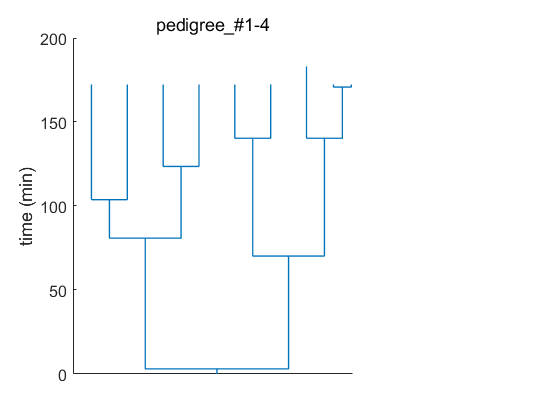

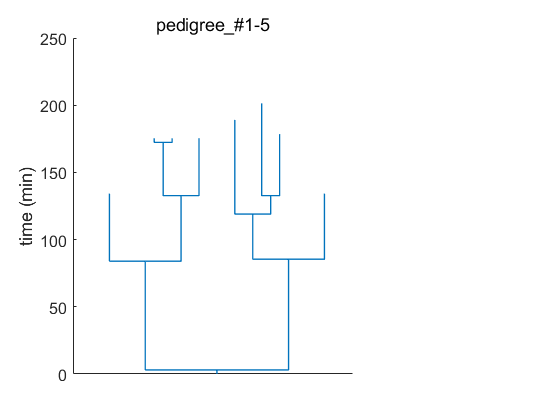

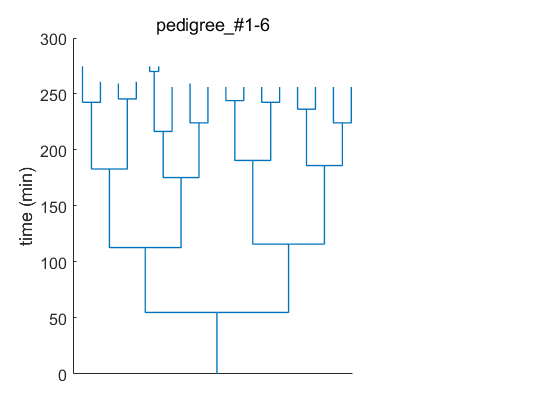

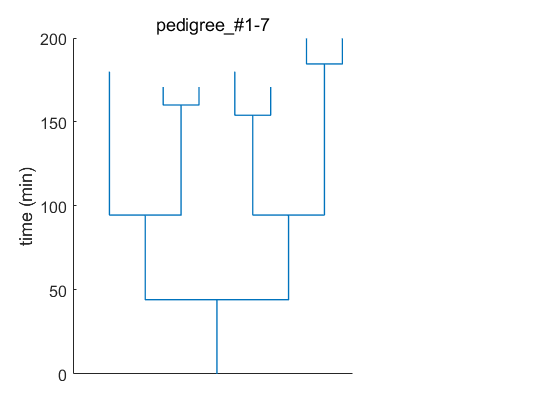

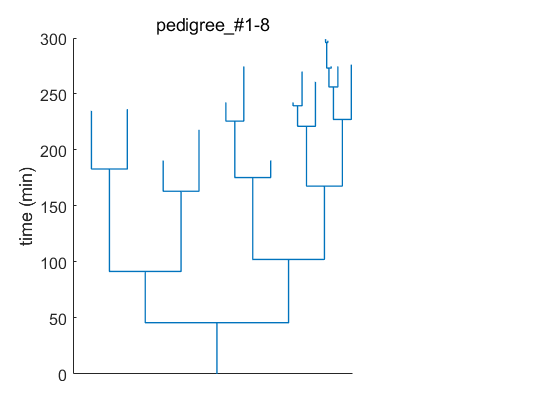

%x位置进行自己定义，y为时间，用直线连接生成genealogicalTree

% shuai Yang 2020.05.11
labelPos = cellXpositonAllocation;

for i = 1:numel(pedigreeAll)
    [leafLabels] = leafLabelsGeneration(pedigreeAll,i);
    fname = strcat('pedigree_#',num2str(pedigreeAll(i).frameIdx),'-',num2str(pedigreeAll(i).rootIdx));
    
    
    for iLeaf = 1:pedigreeAll(i).leafNum
        if pedigreeAll(i).tree(iLeaf).label==1 % 如果label等于1 root标签
            
            cellLabel = pedigreeAll(i).tree(iLeaf).label;
            linePts = zeros(2,2);
            linePts(:,1) = labelPos(cellLabel,2);%x position
            linePts(1,2) = pedigreeAll(i).tree(iLeaf).timer(1);%y  time
            linePts(2,2) = pedigreeAll(i).tree(iLeaf).timer(end);%y  time
            
            
        else
            %不等于1，linePts需要一个直角∟拐点
            cellLabel = pedigreeAll(i).tree(iLeaf).label;
            linePts = zeros(3,2);
            linePts(3,1) = labelPos(cellLabel,2);%x position
            linePts(2,1) = linePts(3,1);% ∟ 2,3的x位置一样
            linePts(3,2) = pedigreeAll(i).tree(iLeaf).timer(end);%ytime
            
            motherLabel = fix(pedigreeAll(i).tree(iLeaf).label/2);%找到其母代细菌的label
            posIdx = find(leafLabels == motherLabel);%根据label找位置
            linePts(1,:) = pedigreeAll(i).tree(posIdx).linePts(end,:);
            linePts(2,2) = linePts(1,2);%1,2点的y位置一样
            
        end
        
        pedigreeAll(i).tree(iLeaf).linePts =linePts;
    end
    
    treePlot_lineLink(i,fname,pedigreeAll)
end

%subfunction

function [leafLabels] = leafLabelsGeneration(pedigreeAll,i)
leafLabels = zeros(pedigreeAll(i).leafNum,1);
for iLeaf = 1:pedigreeAll(i).leafNum
    leafLabels(iLeaf)=pedigreeAll(i).tree(iLeaf).label;
end

end 

% label与xpositon分配

%按最多分裂九代 最终共256个细菌，

%第八代的label为256-511

%第八代的label为128-255，第七代为64-127

%第六代的label为32-63，第五代为16-31

%第四代的label为8-15，第三代为4-7

%第二代的label为2-3，第一代为1

function labelPos = cellXpositonAllocation()
%g 为代数 分配位置2^g-1;细菌数目2^(g-1)个
%第一列为label的数字
%第二列为给分配的x位置
g=9;
labelPos = zeros (2^g-1,2);
labelPos(:,1) = 1:2^g-1;
%先给256-511分配位置为[1,256]
labelPos(2^(g-1):2^g-1,2) = 1 :2^(g-1);

%给剩下的1-255 分配位置,255为510和511的中间值
for i = 2^(g-1)-1 :-1:1
    labelPos(i,2) = (labelPos(i*2,2)+labelPos(i*2+1,2))/2;
end

end

%plot function

function treePlot_lineLink(i,fname,pedigreeAll)

% close all
figure,
f1 = figure('Name',fname);
% set(f1,'visible','off')
axes1 = axes('Parent',f1,'Position',[0.13 0.11 0.5 0.8]);
% hold(axes1,'on');
for iLeaf = 1:pedigreeAll(i).leafNum
    linePts = pedigreeAll(i).tree(iLeaf).linePts;
    line(linePts(:,1),linePts(:,2),'Color',[0,0.45,0.74],'LineWidth',1)
    hold on
end
ylabel({'time (min)'});
title(fname,'Interpreter','none');

% hold(axes1,'off')
hold off
set(axes1,'FontSize',12,'XTick',zeros(1,0));

% saveas(f1,[dirSave,'\',fname,'.fig'])


end